# Wavelet散乱変換を用いた特徴抽出と機械学習による異音判定

以下では、1つの健全な状態と7つの異なる異常の状態を有する空気圧縮機の異音判定のアルゴリズムを示しています。

音声データはいずれも16 kHzで取得されています。

Wavelet散乱変換による特徴抽出は以下のページをご参照ください。

[https://jp.mathworks.com/help/wavelet/ug/music-genre-classification-using-wavelet-scattering.html](https://jp.mathworks.com/help/wavelet/ug/music-genre-classification-using-wavelet-scattering.html)

以下のページではWavelet散乱変換を用いた特徴抽出とSVMによる異音判定の例題が示されています。

[https://jp.mathworks.com/help/wavelet/ug/spoken-digit-recognition-with-wavelet-scattering-and-deep-learning.html](https://jp.mathworks.com/help/wavelet/ug/spoken-digit-recognition-with-wavelet-scattering-and-deep-learning.html)

デモに必要な製品一覧：

- Audio Toolbox™

- DSP System Toolbox™

- Signal Processing Toolbox™

- Statistics and Machine Learning Toolbox™

- Wavelet Toolbox™

## 初期化

clear; close all;
format short; format compact;
% 乱数群の制御
rng('default');

## データの読み込み

filepath = 'C:\Users\xwang\OneDrive - MathWorks\06_Presentation\05_Demos\00_dataset\03_airCompressor\AirCompressorDataSet';
ads = audioDatastore(filepath,'IncludeSubfolders',true,...
    'LabelSource','foldernames'); %* フォルダ名 = ラベル

## データの分割：学習用 + 検証用 + テスト用

ads = shuffle(ads);
[adsTrain,adsValidation,adsTest] = splitEachLabel(ads,0.7,0.2,0.1);

## データの構成を確認：学習用 + 検証用 + テスト用

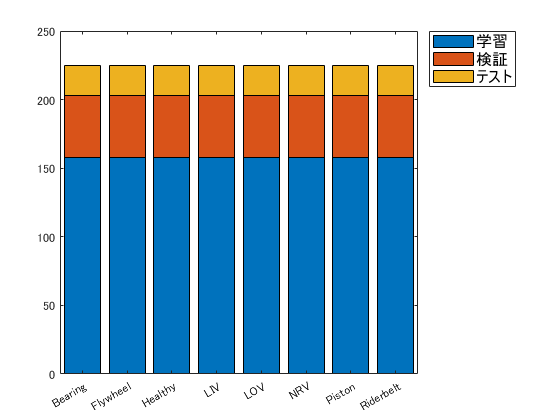

uniqueLabels = unique(adsTrain.Labels);
tblTrain = countEachLabel(adsTrain);
tblValidation = countEachLabel(adsValidation);
tblTest = countEachLabel(adsTest);
H = bar(uniqueLabels,[tblTrain.Count, tblValidation.Count, tblTest.Count],'stacked');
legend(H,{'学習','検証','テスト'},'Location','NorthEastOutside','FontSize',12)

## データの可視化

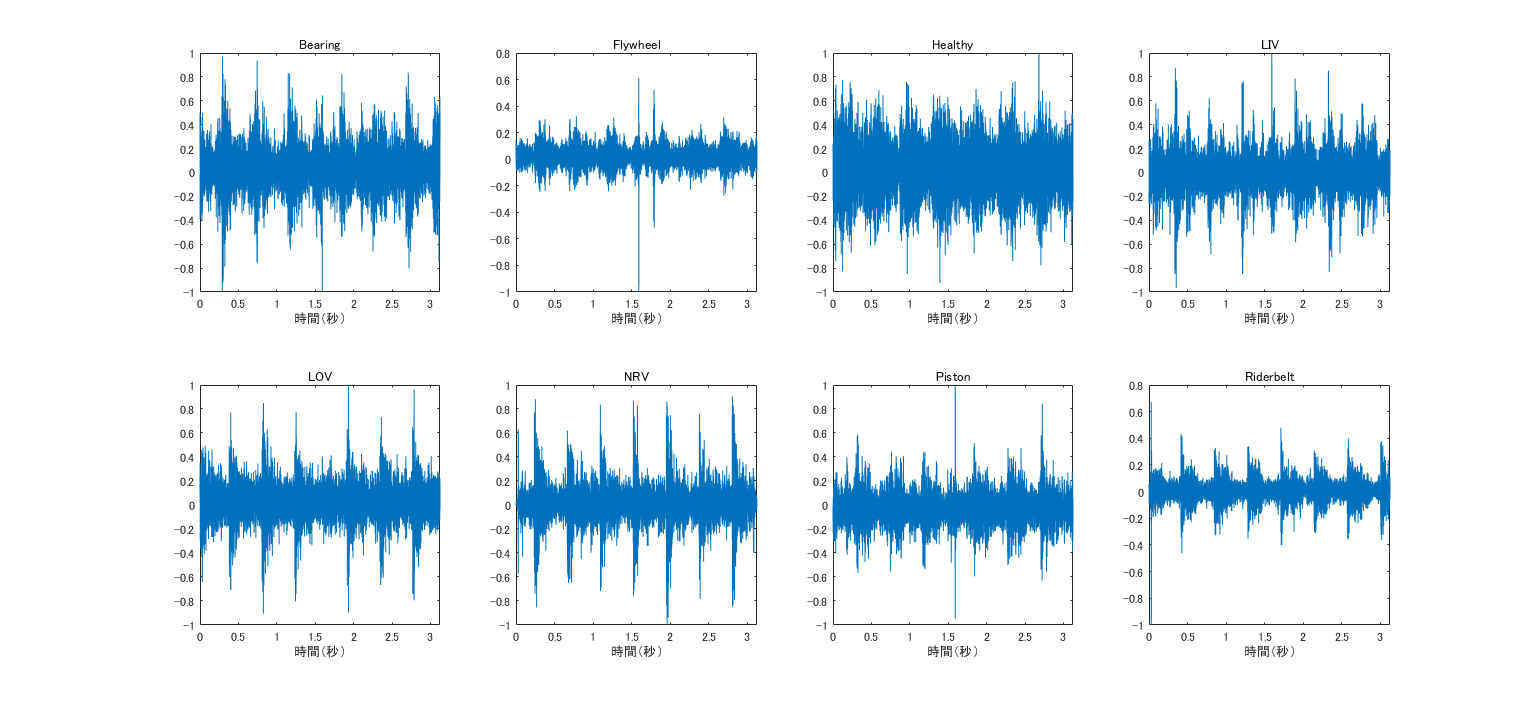

figure('Name','Imported data','Units','Normalized','Position',[0.05, 0.25, 0.80, 0.65]);
for n = 1:numel(uniqueLabels)
    idx = find(adsTrain.Labels==uniqueLabels(n),1);
    [x,fs] = audioread(adsTrain.Files{idx});
    
    t = (0:size(x,1)-1)/fs;
    
    subplot(2,4,n);
    plot(t,x);
    xlabel('時間（秒）')
    title(string(uniqueLabels(n)));
end

## Wavelet散乱変換の設定

s = read(adsTrain);
reset(adsTrain);

e = (nextpow2(numel(s))-1);
N = 2^e;
batchsize = 64;
useGPU = false; % Set to true to use the GPU

sn = waveletScattering('SignalLength',N,'SamplingFrequency',16*10^3,...
    'InvarianceScale',0.5);

## 学習用データの作成

scTrain = [];

tic
while hasdata(adsTrain)
    sc = helperbatchscatfeatures(adsTrain,sn,N,batchsize,useGPU);
    scTrain = cat(3,scTrain,sc);
end
toc

経過時間は 31.711431 秒です。


numTimeWindows = size(scTrain,2);

## テスト用データの作成

scTest = [];

tic
while hasdata(adsTest)
   sc = helperbatchscatfeatures(adsTest,sn,N,batchsize,useGPU);
   scTest = cat(3,scTest,sc); 
end
toc

経過時間は 5.115685 秒です。


## データ構造の調整

[~,npaths] = sn.paths();
Npaths = sum(npaths);
TrainFeatures = permute(scTrain,[2 3 1]);
TrainFeatures = reshape(TrainFeatures,[],Npaths,1);
TestFeatures = permute(scTest,[2 3 1]);
TestFeatures = reshape(TestFeatures,[],Npaths,1);

## ラベリング

trainLabels = adsTrain.Labels;
numTrainSignals = numel(trainLabels);
trainLabels = repmat(trainLabels,1,numTimeWindows);
trainLabels = reshape(trainLabels',numTrainSignals*numTimeWindows,1);

testLabels = adsTest.Labels;
numTestSignals = numel(testLabels);
testLabels = repmat(testLabels,1,numTimeWindows);
testLabels = reshape(testLabels',numTestSignals*numTimeWindows,1);

## 機械学習：学習器の設定（SVM）

template = templateSVM(...
    'KernelFunction', 'polynomial', ...
    'PolynomialOrder', 3, ...
    'KernelScale', 'auto', ...
    'BoxConstraint', 1, ...
    'Standardize', true);

classificationSVM = fitcecoc(...
    TrainFeatures, ...
    trainLabels, ...
    'Learners', template, ...
    'Coding', 'onevsone','ClassNames',uniqueLabels);

## テスト：精度検証

predLabels = predict(classificationSVM,TestFeatures);
[TestVotes,TestCounts] = helperMajorityVote(predLabels,adsTest.Labels,uniqueLabels);
testAccuracy = sum(eq(TestVotes,adsTest.Labels))/numTestSignals*100

testAccuracy = 99.4318

## 混同行列

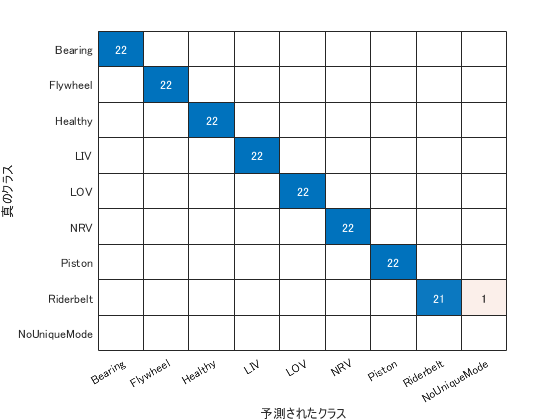

figure; clf;
% confusionchart(TestVotes,adsTest.Labels)
confusionchart(adsTest.Labels,TestVotes)

## 精度の可視化

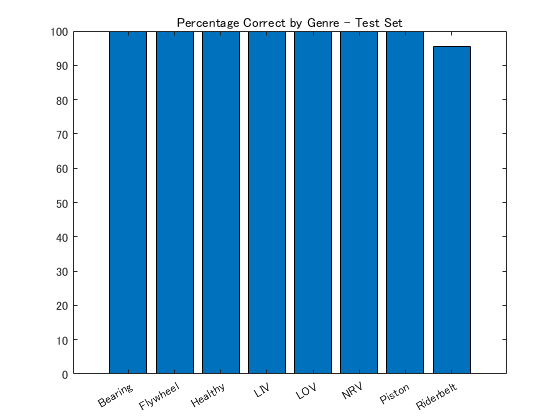

% cm = confusionmat(TestVotes,adsTest.Labels);
cm = confusionmat(adsTest.Labels,TestVotes);
cm(:,end) = [];
genreAccuracy = diag(cm)./tblTest.Count*100;
figure;
bar(genreAccuracy)
set(gca,'XTickLabels',uniqueLabels);
xtickangle(gca,30);
title('Percentage Correct by Genre - Test Set');

**helperbatchscatfeatures** - This function returns the wavelet time scattering feature matrix for a given input signal. In this case, we use the natural logarithm of the wavelet scattering coefficients. The scattering feature matrix is computed on $2^{19}$ samples of a signal. The scattering features are subsampled by a factor of 6. If `useGPU` is set to `true`, the scattering transform is computed on the GPU.

function sc = helperbatchscatfeatures(ds,sn,N,batchsize,useGPU)
% This function is only intended to support examples in the Wavelet
% Toolbox. It may be changed or removed in a future release.

% Read batch of data from audio datastore
batch = helperReadBatch(ds,N,batchsize);
if useGPU
    batch = gpuArray(batch);
end

% Obtain scattering features
S = sn.featureMatrix(batch,'transform','log');
gather(batch);
S = gather(S);
    
% Subsample the features
sc = S(:,1:6:end,:);
end

**helperReadBatch** - This function reads batches of a specified size from a datastore and returns the output in single precision. Each column of the output is a separate signal from the datastore. The output may have fewer columns than the batchsize if the datastore does not have enough records.

function batchout = helperReadBatch(ds,N,batchsize)
% This function is only in support of Wavelet Toolbox examples. It may
% change or be removed in a future release.
%
% batchout = readReadBatch(ds,N,batchsize) where ds is the Datastore and
%   ds is the Datastore
%   batchsize is the batchsize

kk = 1;

while(hasdata(ds)) && kk <= batchsize
    tmpRead = read(ds);
    batchout(:,kk) = cast(tmpRead(1:N),'single'); %#ok<AGROW>
    kk = kk+1;
end

end